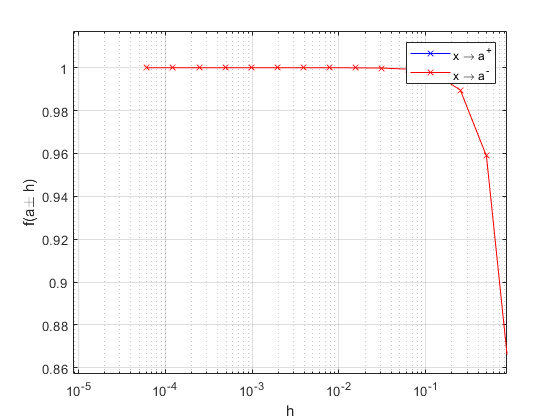

% Skript som estimerar ei grense.
% Uttrykket vi skal ta grensa av, f, og verdien x skal 
% gå mot, a, er hardkoda i starten av skriptet.
% Skriptet plottar f(a+h) for h-verdiar stadig nærare
% null. Den plottar estimatet for både negative og positive 
% verdiar av h.

% Verdien x skal gå mot
a=0;
% Funksjonsuttrykk
f=@(x) sin(x)/x;

h=1;
% Løkke der h blir halvert for kvar iterasjon
for n=1:15
  x=a+h;                            % Oppdaterar x
  Hvektor(n)=h;                     % Lagar vektor med h-verdiar
  GrenseVektorPluss(n)=f(x);        % Når x går mot a ovanfrå
  x=a-h;                            % Oppdaterar x
  GrenseVektorMinus(n)=f(x);        % Når x går mot a nedanfrå
  h=h/2;                            % Halverar h
end

% Plottar estimat
semilogx(Hvektor,GrenseVektorPluss,'bx-')
hold on
semilogx(Hvektor,GrenseVektorMinus,'rx-')
hold off
grid on                             % Rutenett
% Tekstboks med forklaring og tekst på aksar
xlabel('h')
ylabel('f(a\pm h)')
legend('x \rightarrow a^+','x \rightarrow a^-')